**Practica 03 Métodos de conteo **

**Nombre: **Fernando Eliceo Huilca Villagomez  **                  Fecha: **25/01/2024

% Encabezado...
disp('-----------------------------------------------');

-----------------------------------------------


disp('PRACTICA 03. METODOS DE CONTEO');

PRACTICA 03. METODOS DE CONTEO


disp('-----------------------------------------------');

-----------------------------------------------


disp('  Nombre: Fernando Huilca');

  Nombre: Fernando Huilca


disp('  Fecha: 25/01/2024');

  Fecha: 25/01/2024


disp('  Profesor: Andrés Larco');

  Profesor: Andrés Larco


disp('-----------------------------------------------');

-----------------------------------------------


The proctile problem with zero air resistance in a gravitational field with constant g.

### **1. Definition of the input variables**.

g = 9.81; % Gravity in m/s.
vo = input('What is the launch speed in m/s?');
tho = input('What is the launch angle in degrees?');
tho = pi*tho/180; % Conversion of degrees to radians.

### 2. Calculate the range and duration of the flight.

txmax = (2*vo/g) * sin(tho);
xmax = txmax * vo * cos(tho);

### 3. Calculate the sequence of time steps to compute trajectory.

dt = txmax/100;
t = 0:dt:txmax;

### 4. Compute the trajectory.

x = (vo * cos(tho)) .* t;
y = (vo * sin(tho)) .* t - (g/2) .* t.^2;

### 5. Compute the speed and angular direction of the projectile.

Note that vx = dx/dt, vy = dy/dt.

vx = vo * cos(tho);
vy = vo * sin(tho) - g .* t;
v = sqrt(vx.*vx + vy.*vy);
th = (180/pi) .* atan2(vy,vx);

### 6. Compute the time, horizontal distance at maximum altitude

tymax = (vo/g) * sin(tho);
xymax = xmax/2;
ymax = (vo/2) * tymax * sin(tho);

### 7. Display ouput.

disp(['Range in m = ',num2str(xmax),'Duration in s = ',num2str(txmax)])

Range in m = 100.3397Duration in s = -5.2103


disp(' ')

disp(['Maximum altitude in m = ',num2str(ymax),' Arrival in s = ',num2str(ymax)]) 

Maximum altitude in m = 33.2888 Arrival in s = 33.2888


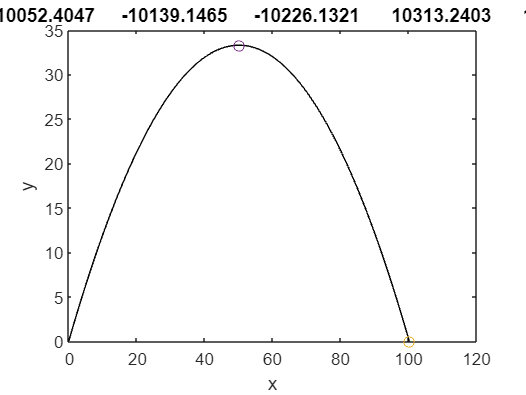

plot(x,y,'k',xmax,y(size(t)),'o',xmax/2,ymax,'o')
title(['Projectile flight path, vo =',num2str(vo),' th =', num2str(180*th/pi)])
xlabel('x'), ylabel('y') % Plot of Figure 1.

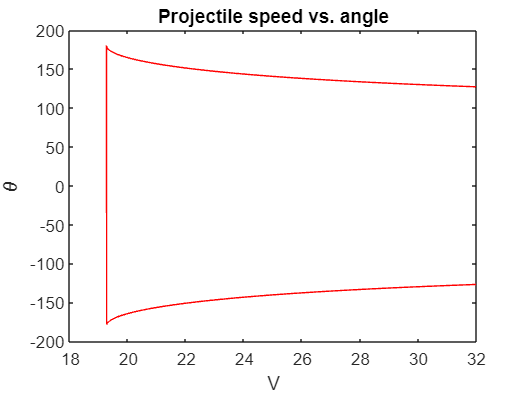

figure % Creates a new figure.
plot(v,th,'r')
title('Projectile speed vs. angle')
xlabel('V'), ylabel('\theta') % Plot of Figure 2.

### 8. Stop.

**Varios gráficos en una figura:**

Este script ilustra cómo poner cuatro gráficos en una ventana de una sola figura.

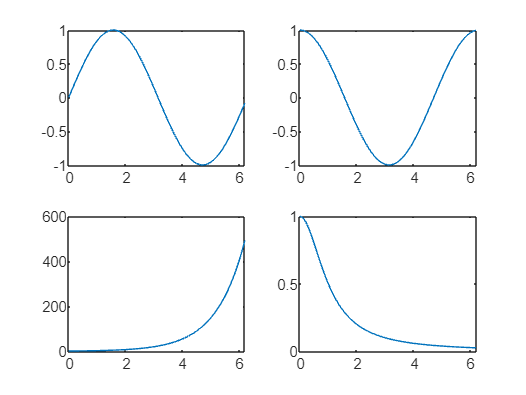

t = (0:.1:2*pi)';
subplot(2,2,1)
plot(t,sin(t))
subplot(2,2,2)
plot(t,cos(t))
subplot(2,2,3)
plot(t,exp(t))
subplot(2,2,4)
plot(t,1./(1+t.^2))

**Inline objects: Harmonic oscillators**

Si dos osciladores armónicos acoplados, por ejemplo, dos masas conectadas con un resorte en una mesa muy suave, se consideran como un solo sistema, la salida del sistema en función del tiempo t podría estar dado por algo como

*h(t) = cos(8t) + cos(9t).*

Puede representar h (t) en la línea de comando creando un objeto en línea de la siguiente manera:

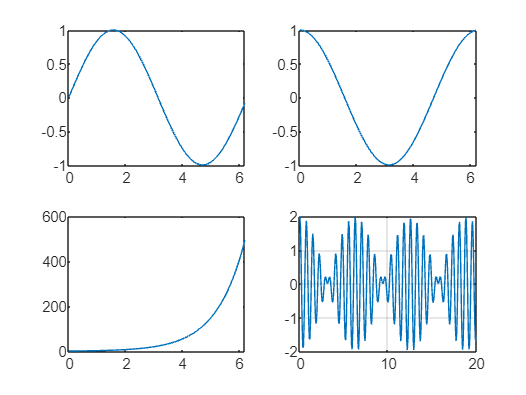

h = inline( 'cos(8*t) + cos(9*t)'); % función
x = 0 : 20/300 : 20;
plot(x, h(x)), grid

pascal(4)

ans =      1     1     1     1
     1     2     3     4
     1     3     6    10
     1     4    10    20


Consideremos el arco-coseno, el arco-seno y las funciones arco-tangente, es decir, acos (x), asin (x) y atan (x), respectivamente.

The question raised is: What range of angles, i.e., which of the four quadrents of the circle from 0 to 2*pi are the angular outputs of each of the functions?

Assign the values of x to be examined:

x = -1:0.001:1;

Compute the arc-functions:

y1 = acos(x);
y2 = asin(x);
y3 = atan(x);

Convert the angles from radians to degrees:

y1 = 180*y1/pi;
y2 = 180*y2/pi;
y3 = 180*y3/pi;

 Plot the results:

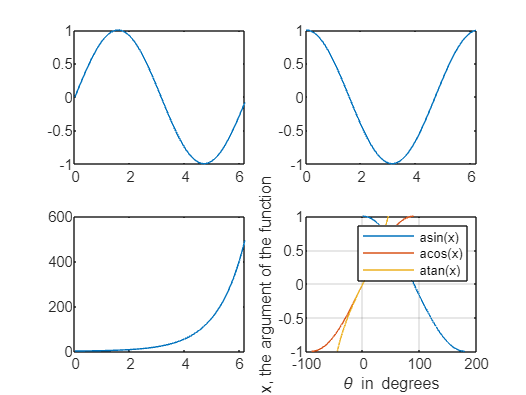

plot(y1,x,y2,x,y3,x),grid
legend('asin(x)', 'acos(x)', 'atan(x)')
xlabel('\theta in degrees')
ylabel('x, the argument of the function')

REMARKS: Note the following:

(1) The acos(x) varies from 0 to 90 to 180 degrees.

(2) The asin(x) varies from -90 to 0 to 90 degrees.

(3) The atan(x) varies from -90 to 0 to 90 degrees.

To check remark (3) try atan(10000000) *180/pi.

Stop